## TOPIC 2: Introduction to arrays: vectors, matrices, and more

ENGR105, 9/8/20

### Revisiting vectors

Previously, we learned how to *create vectors*,* access vector elements*, and *delete vector elements*. We did this for *row* vectors, the default orientation of vectors formed by slice notation, linspace, etc.

For example, consider operations on the following row vector, which has one row and four columns.

% Create an example vector
x = 1:2:8

x =      1     3     5     7


% Call indices 1 and 4 of vector x
x([1,4])

ans =      1     7


% Delete the element associated with the index 4
x(4) = []

x =      1     3     5


% Create new vectors via concatenation
x1 = [x,x]

x1 =      1     3     5     1     3     5


x2 = [x,linspace(1,3,6)]

x2 =     1.0000    3.0000    5.0000    1.0000    1.4000    1.8000    2.2000    2.6000    3.0000


Why are we doing this?

- Array operations are a fundamental component of using MATLAB.

- If you know how to create vectors and matrices, you can "easily" solve engineering problems (goal for this week).

- Practice using "logic" and math concepts to try to create something new in the most efficient way possible.

#### Example

Starting with vector `x`, defined below, perform the following steps:

x = [1,4,2,5,6,4,3,1,4,2,5,6,4,3,1,4,2,5,6,4,3];

- Delete very 4th entry starting with the first.

- Square every odd element.

- Move the last 5 entries to the front

% Step 1
x(1:4:end) = [];
% Step 2
x(1:2:end) = x(1:2:end).^2;
% Step 3
%end is an inclusive range 
%we concatinate a new vector that starts with the last 5 numbers and
%carries on to the first 5 numbers 
x = [x(end-4:end), x(1:end-5)]

x =      1     4    25     6    16    16     2    25     4     9     1     4     5    36     3


#### Column vectors

*Column* vectors can be created via direct input (i.e. explicitly defining the vector) or the transpose (`'`) command.

- Column vector created using semicolons

x = [5; 4; 6; 9]

x =      5
     4
     6
     9


- Column vector created using the **transpose**

% Creating a new column vector
y1 = (1:4)';
% Creating a new vector by taking the transpose of an existing one
y2 = x'

y2 =      5     4     6     9


Live row vectors, a created column vector may be addressed using single index notation to refer to rows. 

- Single index notation: specifying an index or range of indices using a vector. This is exactly what we used proviously.

x = [5; 2; 1; 8]

x =      5
     2
     1
     8


% Replacing the first element
x(1) = 9

x =      9
     2
     1
     8


% Replacing the first two elements
x(1:2) = [4, 3]

x =      4
     3
     1
     8


% Replacing the second-to-last element
x(end-1) = 9

x =      4
     3
     9
     8


% Deleting the first and third elements
x([1,3]) = []

x =      3
     8


In other words, the same index notation is used for both row and column vectors. Though we will often use row vectors because these are the default orientation, it is important to remember that the vector you have created has a particular orientation.

#### Determining the number of entries in a vector

It is sometimes helpful to know the length of a vector in order to perform operations based on its size. Use the `length()` command to determine the number of entries in a vector.

x = [5, 2, 1, 4, 9, 1]

x =      5     2     1     4     9     1


L = length(x)

L = 6

You can use `length()` to operate on, e.g. the first half of a vector, even if you don't know it's size beforehand.

% Return the first half of the vector
x(1:length(x)/2)

ans =      5     2     1


Reminder: if you assign a scalar to a vector, as below, the scalar will assigned to all indices of the specified vector.

x(1:length(x)/2) = 50;
x

x =     50    50    50     4     9     1


#### Precedence

Note a detail in the above code:

1:length(x)/2

ans =      1     2     3


This is not the same as the following, due to precedence.

%Divides the original vector length in half 
(1:length(x))/2

ans =     0.5000    1.0000    1.5000    2.0000    2.5000    3.0000


This is because MATLAB follows an order of operations for vector and array operations. 

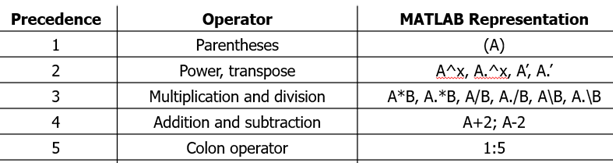

The colon operator takes the lowest precedence and so the following are equivalent:

1:length(x)/2

ans =      1     2     3


1:(length(x)/2)

ans =      1     2     3


We can add to the classic order of operations mnemonic: "Please Excuse My Dear Aunt Sally's Colon"

Operation precedence may be overidden using parentheses.

a = 1;
b = 2;
c = 3;
d = 4;

Consider the following examples

- Statements are evaluated from left to right with multiplication and division being executed first

a+b*c/d

ans = 2.5000

- Here, the parentheses specify that addition should be executed first (overriding mathematical precedence)

(a+b)*c/d

ans = 2.2500

- Upholds the execution order prescribed by mathematical operator precedence, the use of parentheses is unnecessary

a+(b*c)/d

ans = 2.5000

Parentheses can be included to improve the clarity of an expression even if not modifying precedence 

- z1 = 2*pi*x^2*y+1;

- z2 = 2*pi*(x^2*y)+1;

`z1` and `z2` give the same result, but it is easier to see the relationships between pre-factors and independent variables in `z2`

### Arrays

A *vector* is only one type of *array*. MATLAB stands for Matrix Laboratory because the MATLAB system is designed to efficiently work with data arranged in arrays of all sizes, especially 2-D *matrices*. In fact, all numbers in MATLAB are stored as arrays:

- **Scalar**: (`1x1` array)

a1 = 1;
disp(a1)

     1



- **Vector**: (`1xN` array) or (`Nx1` array). In this case, there are either N rows or N columns

a2 = [1,5,9];
disp(a2)

     1     5     9



a3 = [1;5;9];
disp(a3)

     1
     5
     9



- **2D matrix**: (`MxN` array). That is, a 2D matrix consists of M rows and N columns. In this case, there are 2 rows and 3 columns.

%remember the semicolon makes the vector an array
a4 = [1,5,9;9,5,1];
disp(a4)

     1     5     9
     9     5     1



- **Multidimensional matrix**: (`MxNx...xP` array). A 3D+ array consists of rows, columns, "pages", "volumes", etc. In this case there are 2 rows, 3 columns, and 2 "pages."

a5(:,:,1) = [1,5,9;9,5,1];
a5(:,:,2) = [2,3,4;4,3,2];
disp(a5)


(:,:,1) =

     1     5     9
     9     5     1


(:,:,2) =

     2     3     4
     4     3     2



#### Dimensions of an array

The `length(),` `size()`, and `numel() `commands are useful for evaluating the properties of an array.

- As seen above, `length()` is useful for vectors --it returns the number of elements in the vector. This command operates independently of the vector being a row or column vector.

length(a2)

ans = 3

length(a3)

ans = 3

- Using length on a matrix is less useful -- in general, it returns the greatest dimension of the array

length(a4)

ans = 3

- To evaluate the dimensions of an arbitrary-sized array, use the `size()` function. This functions returns a **vector**:

size(a4)

ans =      2     3


This can be read as, "a4 is a `2x3` matrix." The first entry represents the number of rows of a4, the second entry represents the number of columns.

- size() can be used for higher-order arrays also

size(a5)

ans =      2     3     2


This can be read as, "a5 is a `2x3x2` matrix." The first entry represents the number of rows of a4, the second entry represents the number of columns.

- The `numel``()` command returns the total number of indices ("number of elements") in the array.

numel(a4)

ans = 6

### Matrices

For now, we will focus on 2D matrices. For simplicity we will call these "matrices," but it is implied that we mean 2D matrices or 2D arrays. You will work with matrices a lot in your linear algebra courses, as well as advanced engineering courses.

- *Relevant UPenn Course*: ENM 240 Differential Equations and Linear Algebra

- *Relevant UPenn Course*: MATH 240: Calculus, pt. III

#### Constructing matrices

Matrices may be explicitly constructed by inputting row and column values as a list. A semicolon divides rows.

A = [2, 5, 9; 6, 8, 3]

A =      2     5     9
     6     8     3


Matrices may also be constructed from existing vectors using concatenation. **Note the orientation of the vectors.**

a = [1, 2, 3];
b = [4, 5, 6];
% Concatenate vertically
A1 = [a;b]

A1 =      1     2     3
     4     5     6


% Concatenate horizontally
A2 = [a,b]

A2 =      1     2     3     4     5     6


a = [1; 2; 3];
b = [4; 5; 6];
% Concatentate
B1 = [a;b]

B1 =      1
     2
     3
     4
     5
     6


**NOTE: Dimensions must match along the plane of concatenation**

For vectors:

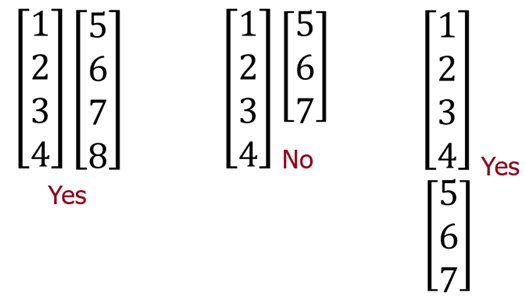

For matrices:

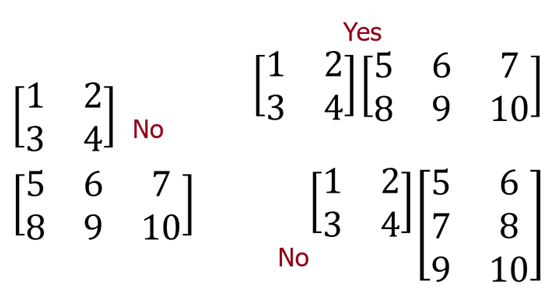

Takeaway: **be aware of the dimensions of the vectors and matrices you are working with.**

% Concatenate vectors
a = [1 2 3; 4 5 6]

a =      1     2     3
     4     5     6


b = [7 8 9; 10 11 12]

b =      7     8     9
    10    11    12


% Concatenate matrices
C1 = [a;b]

C1 =      1     2     3
     4     5     6
     7     8     9
    10    11    12


C2 = [a,b]

C2 =      1     2     3     7     8     9
     4     5     6    10    11    12


#### Accessing array indices

Specific indices from a 2D matrix can be accessed by row and column indexing in the form **Matrix(row, column).**

A = [1:3;4:6;7:9]'

A =      1     4     7
     2     5     8
     3     6     9


A(3,1)

ans = 3

A(1,3)

ans = 7

In the above, we took the **transpose** of a matrix. This swaps the row and column index of every element. For example, the following `2x3` matrix becomes a `3x2` matrix.

B = [1:3;4:6]

B =      1     2     3
     4     5     6


B'

ans =      1     4
     2     5
     3     6


**Useful**: Full rows or columns can be selected using the colon operator (`:`).

A = [1:3;4:6;7:9]'

A =      1     4     7
     2     5     8
     3     6     9


% Return a column vector of all rows in the first column
A(:,1)

ans =      1
     2
     3


%Colon returns all columns in that row?
% Return a row vector of all columns in the second row
A(2,:)

ans =      2     5     8


Submatrices may also be extracted.

% Return a submatrix of entries in first and second rows and columns
A(1:2,1:2)

ans =      1     4
     2     5


% Return a submatrix of entries in first and second rows and all columns
A(1:2,:)

ans =      1     4     7
     2     5     8


In my opinion, row and column indexing is preferred because it is more intuitive. However, array indices may also be accessed using a single subscript indexing (“unwound” matrix). Indices are evaluated starting in the upper left hand corner and parsed by column.

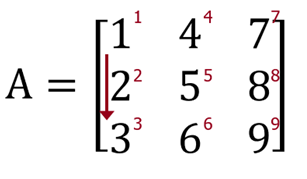

A(5)

ans = 5

A range of entries may be called to return a row vector of the corresponding elements.

A(1:5)

ans =      1     2     3     4     5


Note: the colon operator (:) may be used to unwind the entire matrix into a *column vector*.

A(:)

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9


The diagonal components of a matrix may be called using the `diag()` command. Often, these elements are important for engineering applications - e.g. normal stresses from a stress tensor.

% Diagonal components of A
diag(A)

ans =      1
     5
     9


#### Overwriting indices

Specific indices of the matrix may be directly overwritten using row/column or single subscript notation.

A = [1:3;4:6;7:9]'

A =      1     4     7
     2     5     8
     3     6     9


% Replace the entry in the third row, first column
A(3,1) = 50

A =      1     4     7
     2     5     8
    50     6     9


% Replace all entries in the "upper left of the matrix"
A(1:2,1:2) = 0

A =      0     0     7
     0     0     8
    50     6     9


If a matrix index is assigned a value outside of the original matrix size, indices of "unknown value" will be padded with 0’s

A(4,4) = 33

A =      0     0     7     0
     0     0     8     0
    50     6     9     0
     0     0     0    33


Array indices at any index location can be specified even if the array does not exist. 

% C has not be previously defined
C(3,3,3) = 1

C = C(:,:,1) =

     0     0     0
     0     0     0
     0     0     0


C(:,:,2) =

     0     0     0
     0     0     0
     0     0     0


C(:,:,3) =

     0     0     0
     0     0     0
     0     0     1


### Array mathematics

#### Addition and Subtraction

General rules for addition and subtraction for arrays of any dimension (e.g. vectors or matrices)

- Scalars may be added to/subtracted from any array -** the scalar value is added to all elements of the array**

- Arrays added to arrays must have the **same dimensions** and elements in correlated index locations can be added or subtracted. 

% Create new matrix
A = [1,5;2,3]

A =      1     5
     2     3


% Add 2 to every element


% Create new array by reordering the first and second row
B = [A(2,:);A(1,:)]

B =      2     3
     1     5


% Matrix addition


Remember: matrix dimensions must agree. In other words, the matrices must have the same dimensions.

#### Multiplication

General rules for matrix/array multiplication:

- Arrays may be multiplied by a **scalar**.

- **Arrays of the same dimensions** may be multiplied index-by-index using the array multiplier/vectorization (`.*`)

- The matrix product (`*`) may be evaluated for matrices if the "inner dimensions" of the original matrices match and the resulting matrix will have dimensions equal to the outer dimensions of the matrices being multiplied.

**Case 1: multiplication by a scalar**

A

A =      1     5
     2     3


**Case 2: element-by-element multiplication**. Arrays of the same dimensions may be multiplied index-by-index using the array multiplier/vectorization (.*)

A

A =      1     5
     2     3


B

B =      2     3
     1     5


**Case 3: matrix multiplication**. For `A*B`, the **columns of A must equal the rows of B**.

The element in the first row and first column of `A*B` is:

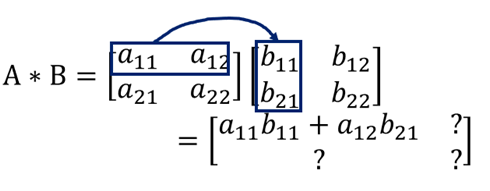

The element in the first row and second column of `A*B` is:

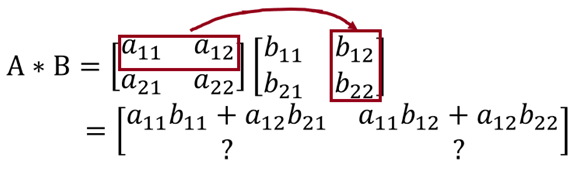

Filling in the matrix:

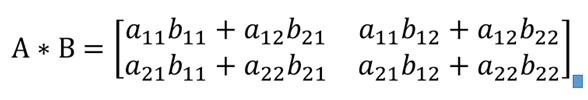

A = [1,4;2,3]

A = 2×2
     1     4
     2     3


B = [1,2;3,4]

B = 2×2
     1     2
     3     4


% Matrix multiplication
A*B

ans = 2×2
    13    18
    11    16


**Remember: A*B is not usually the same as B*A**

% Matrix multiplication with multiplication order reversed.
B*A

ans = 2×2
     5    10
    11    24


**Pro tip:** if you feel stressed about this, write out each entry systematically! You will work a lot more with matrices in your linear algebra courses.

**Remember**: the dimensions of the matrix product are equal to the outer dimensions of the original matrices and the inner dimensions must match

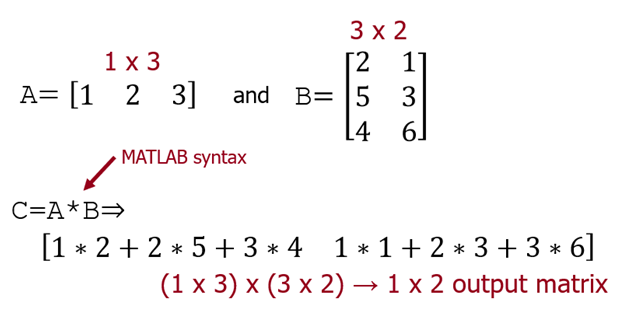

B = [2,1;5,3;4,6]

B = 3×2
     2     1
     5     3
     4     6


A = 1:3

A = 1×3
     1     2     3


% To perform matrix multiplication, ensure the columns of the first matrix
% match the rows of the second
A*B

ans = 1×2
    24    25


#### Division

**Division of a scalar by an array** necessitates an array operator. 

A = [1 2; 4 8]

A = 2×2
     1     2
     4     8


B = 16./A

B = 2×2
    16     8
     4     2


**NOTE**: `B = 16/A` will return an error.

**NOTE**: Matrix division has a different interpretation than scalar division. Right division is different than left division.

**Element-wise division:**

- *Right* division: `A./B` is equivalent to `A(i,j)/B(i,j)` 

- *Left* division:   `A.\B` is equivalent to `B(i,j)/A(i,j) `

% Define matrix A and vector b
A = [2,4;2,6]

A = 2×2
     2     4
     2     6


B = [1,2;1,3]

B = 2×2
     1     2
     1     3


% Perform right division

% Perform left division


**Left matrix division**. Consider the following matrix equation, in which matrix **A** is multiplied by vector **x** to give vector **b**. 

            
$$\textrm{Ax}=\mathbf{b}$$


Note on dimensions: assuming A is square (e.g. `2x2`), then **x** and **b** must be (e.g. `2x1)` column vectors. To solve for **x**, you must perform left division of matrix **A**, or left multiply by the inverse of **A**.

            
$${\mathbf{x}=\mathbf{A}\backslash \textrm{Ax}=\mathbf{A}}^{-1} \textrm{Ax}=\mathbf{A}\backslash \mathbf{b}={\mathbf{A}}^{-1} \mathbf{b}$$


The above works because ${\mathbf{A}}^{-1} \mathbf{A}=\mathrm{I}$, where $\mathrm{I}$ is the identity matrix, and $\textrm{IX}=\mathbf{X}$ (by definition).

% Define matrix A and vector b
A = [2,4;2,6]

A = 2×2
     2     4
     2     6


b = [5;4]

b = 2×1
     5
     4


% Perform left division
A\b

ans = 2×1
    3.5000
   -0.5000


inv(A)*b

ans = 2×1
    3.5000
   -0.5000


**Right matrix division**. Consider the following matrix equation, in which matrix **A** is multiplied by vector **x** to give vector **b**. 

            
$$\textrm{xA}=\mathbf{b}$$


Note on dimensions: assuming A is square (e.g. `2x2`), then **x** and **b** must be (`e.g. 1x2`) row vectors. To solve for **x**, you must perform right division of matrix **A**, or right multiply by the inverse of **A**.

            
$${\mathbf{x}=\textrm{xA}/\mathbf{A}=\textrm{xAA}}^{-1} =\mathbf{b}/\mathbf{A}=\mathbf{b}{\mathbf{A}}^{-1}$$


A = [2,4;2,6]

A = 2×2
     2     4
     2     6


b = [5,4]

b = 1×2
     5     4


% Perform right division
b/A

ans = 1×2
    5.5000   -3.0000


b*inv(A)

ans = 1×2
    5.5000   -3.0000


### Application: solving a set of linear equations

You are likely familiar with canonical linear equations of the form `y=mx+b` or `ax+by=c`, which define a straight line in 2D space. Consider a set of two linear equations:

            
$$\begin{array}{l}
y=m_1 x+b_1 \\
y=m_2 x+b_2 
\end{array}$$


In engineering applications, you are often interested in solving a set of linear equations. There are three possibilities:

**There is one solution.**

              
$$\begin{array}{l}
y=x\\
y=2x-3
\end{array}$$


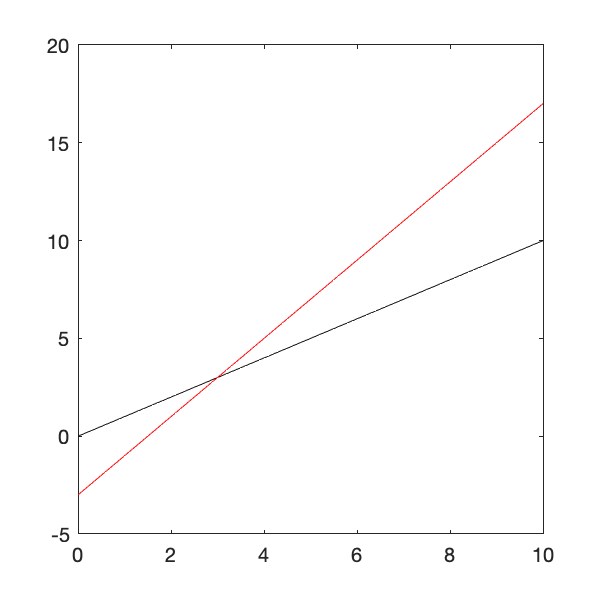

% x vectors
x = 0:.1:10;
% Create a figure window of a defined size
figure('Position',[0,0,300,300]);
plot(x,x,'k-',x,2*x-3,'r-')

**There are no solutions.**

              
$$\begin{array}{l}
y=x\\
y=x-3
\end{array}$$


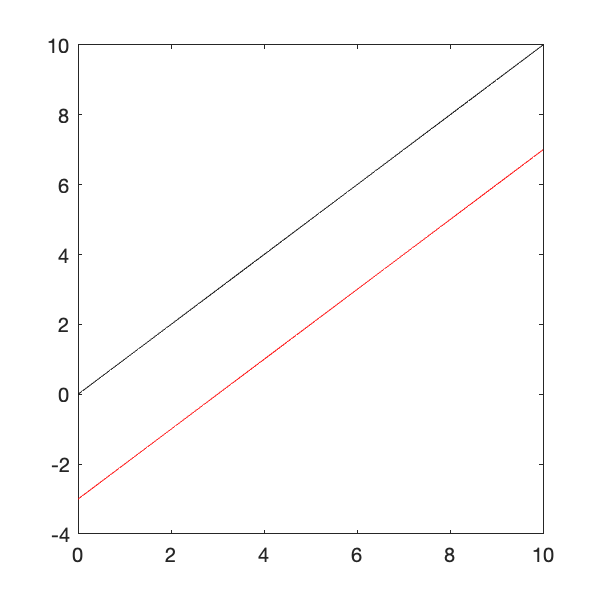

% Create a figure window of a defined size
figure('Position',[0,0,300,300]);
plot(x,x,'k-',x,x-3,'r-')

**There are infinite solutions.**

              
$$\begin{array}{l}
y=x\\
y=x
\end{array}$$


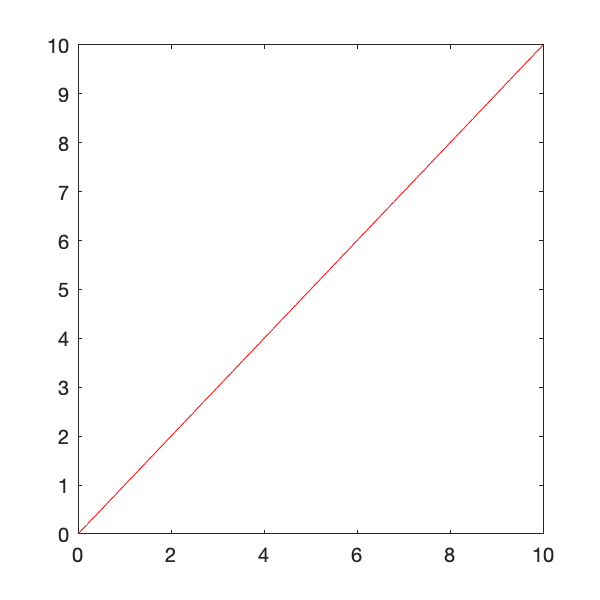

% Create a figure window of a defined size
figure('Position',[0,0,300,300]);
plot(x,x,'k-',x,x,'r-')

We will focus on systems that have one solution. Further study in linear algebra will provide conditions on matrix **A** and vector **b** that will enable you to determine the number of solutions.

#### One approach: substitution

Consider the two equations defined above. To solve, perform the following steps.

             
$$\begin{array}{l}
y=m_1 x+b_1 \\
y=m_2 x+b_2 
\end{array}$$


1) Set equations equal

             
$$m_1 x+b_1 =m_2 x+b_2$$


2) Solve for x

             
$$\begin{array}{l}
\left.x{\left(m\right.}_1 -m_2 \right)=b_2 -b_1 \\
x=\frac{\left(b_2 -b_1 \right)}{\left.{\left(m\right.}_1 -m_2 \right)}
\end{array}$$


3) Substitute to solve for y

             
$$y=m_1 \frac{\left(b_2 -b_1 \right)}{\left.{\left(m\right.}_1 -m_2 \right)}+b_1$$


This is fine, but requires equations in the above form and can get tedious.

#### Another approach: matrix representation

Rearranging the above system of equations:

                
$$\begin{array}{l}
y{-m}_1 x=b_1 \\
y-m_2 x=b_2 
\end{array}$$


Double check the matrix multiplication rules above. Based on the rules of matrix multiplication, the above set of equations can be represented in matrix form:

                
$$\left\lbrack \begin{array}{cc}
1 & {-m}_1 \\
1 & {-m}_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\\
x
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack$$


Or:

                
$$\begin{array}{l}
\textrm{Ax}=\mathbf{b}\\
\mathbf{A}=\left\lbrack \begin{array}{cc}
1 & {-m}_1 \\
1 & {-m}_2 
\end{array}\right\rbrack \\
\mathbf{x}=\left\lbrack \begin{array}{c}
y\\
x
\end{array}\right\rbrack \\
\mathbf{b}=\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack 
\end{array}$$


This is the case above corresponding to **left matrix division**. Thus, we can simply solve for `y` and `x` by performing a left division:

                
$$\mathbf{x}=\mathbf{A}\backslash \textrm{Ax}=\mathbf{A}\backslash \mathbf{b}$$


**Example 1**. Solve the following system of equations. 

                
$$\begin{array}{l}
y=x\\
y=2x-3
\end{array}$$


% Step 1: convert to matrix format
A = [1,-1;1,-2]; %Coefficient matrix defined above
b = [0;-3]; % Constant matrix
% Step 2: solve for x and y


Thus, the solution exists at `x = 3` and `y = 3`.

#### More general representation

More often, you will encounter systems with more than two variable. Thus, it is more convenient to think of a system of linear equations in the following form, where there are `n` variables and `n` equations.

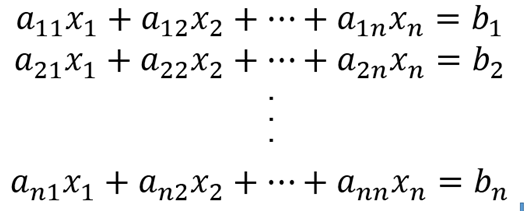

The above can be represented compactly in matrix form:

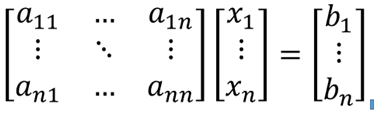

Or again as:

                
$$\textrm{Ax}=\mathbf{b}$$


**Note: matrix **`A`** is slightly different than defined previously. **This is a more general form.

**Example 2. **Solve the following system of equations.

                
$$\begin{array}{l}
x_1 +{3x}_2 +x_3 =1\\
{2x}_1 +{2x}_2 -x_3 =2\\
x_1 +x_2 +x_3 =-2
\end{array}$$


% Step 1: convert to matrix format
A = [1,3,1;2,2,-1;1,1,1]; %Coefficient matrix defined above
b = [1;2;-2]; % Constant matrix
% Step 2: solve for x 


Thus, the solution to this problem is $x_1 =-1\ldotp 5$, $x_2 =1\ldotp 5$, $x_3 =-2$.